APR_LW_Stepplot = readtable("APR_LW_Stepplot.csv");

APR_SW_Boxplot = readtable("APR_SW_Boxplot.csv")

APR_SW_Boxplot = 31×25 table
    Var1     Var2     Var3     Var4     Var5      Var6       Var7       Var8       Var9       Var10      Var11      Var12      Var13      Var14      Var15      Var16      Var17      Var18      Var19      Var20    Var21    Var22    Var23    Var24     Var25 
    _____    _____    _____    _____    _____    _______    _______    _______    _______    _______    _______

AUG_LW_Stepplot = readtable("AUG_LW_Stepplot.csv");

AUG_SW_Boxplot = readtable("AUG_SW_Boxplot.csv");
DEC_LW_Stepplot = readtable("DEC_LW_Stepplot.csv");

DEC_SW_Boxplot = readtable("DEC_SW_Boxplot.csv");
DJF_LW_Stepplot = readtable("DJF_LW_Stepplot.csv");
FEB_LW_Stepplot = readtable("FEB_LW_Stepplot.csv");

FEB_SW_Boxplot = readtable("FEB_SW_Boxplot.csv");
JAN_LW_Stepplot = readtable("JAN_LW_Stepplot.csv");

JAN_SW_Boxplot = readtable("JAN_SW_Boxplot.csv");
JJA_LW_Stepplot = readtable("JJA_LW_Stepplot.csv");
JUL_LW_Stepplot = readtable("JUL_LW_Stepplot.csv");

JUL_SW_Boxplot = readtable("JUL_SW_Boxplot.csv");
JUN_LW_Stepplot = readtable("JUN_LW_Stepplot.csv");

JUN_SW_Boxplot = readtable("JUN_SW_Boxplot.csv");
MAM_LW_Stepplot = readtable('MAM_LW_Stepplot.csv');
MAR_LW_Stepplot =readtable("MAR_LW_Stepplot.csv");

MAR_SW_Boxplot = readtable("MAR_SW_Boxplot.csv");
MAY_LW_Stepplot = readtable("MAY_LW_Stepplot.csv");

MAY_SW_Boxplot = readtable("MAY_SW_Boxplot.csv");
NOV_LW_Stepplot = readtable("NOV_LW_Stepplot.csv");

NOV_SW_Boxplot = readtable("NOV_SW_Boxplot.csv");
OCT_LW_Stepplot = readtable("OCT_LW_Stepplot.csv");

OCT_SW_Boxplot = readtable("OCT_SW_Boxplot.csv");
SEP_LW_Stepplot = readtable("SEP_LW_Stepplot.csv");

SEP_SW_Boxplot = readtable("SEP_SW_Boxplot.csv");
SON_LW_Stepplot = readtable("SON_LW_Stepplot.csv");

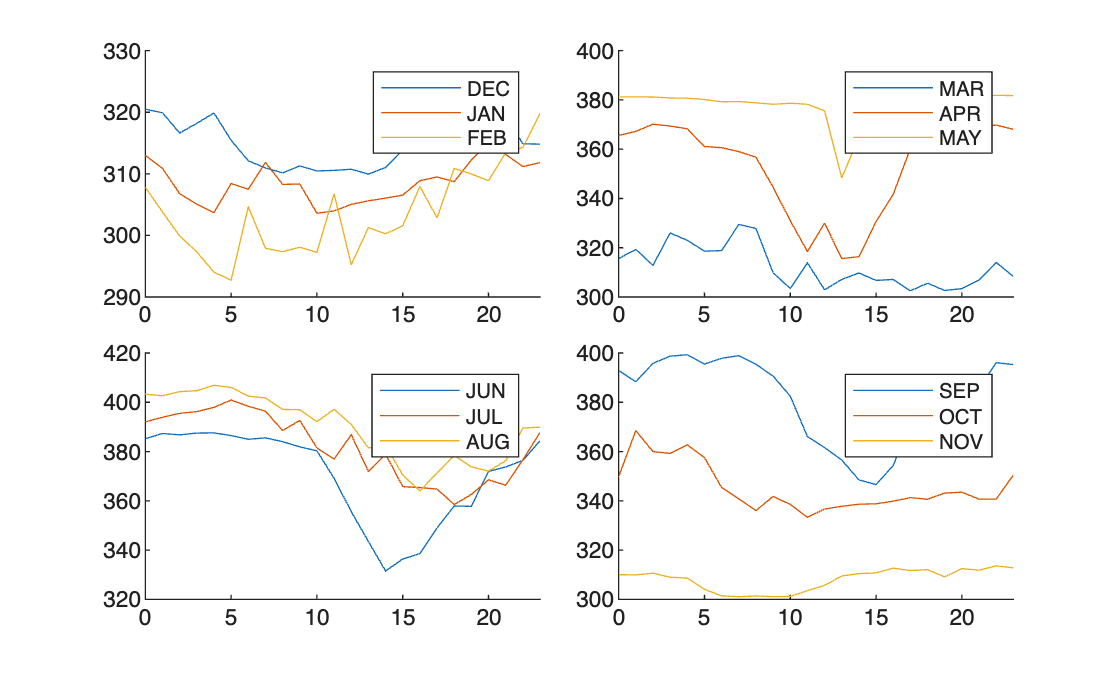

decLW = DJF_LW_Stepplot{:,"DEC"};
janLW = DJF_LW_Stepplot{:,"JAN"};
febLW = table2array(DJF_LW_Stepplot(:,"FEB"));
djftime = table2array(DJF_LW_Stepplot(:,"Hour"));

marLW = table2array(MAM_LW_Stepplot(:,"MAR"));
aprLW = table2array(MAM_LW_Stepplot(:,"APR"));
mayLW = table2array(MAM_LW_Stepplot(:,"MAY"));
mamtime = table2array(MAM_LW_Stepplot(:,"Hour"));

junLW = table2array(JJA_LW_Stepplot(:,"JUN"));
julLW = table2array(JJA_LW_Stepplot(:,"JUL"));
augLW = table2array(JJA_LW_Stepplot(:,"AUG"));
jjatime = table2array(JJA_LW_Stepplot(:,"Hour"));

sepLW = table2array(SON_LW_Stepplot(:,"SEP"));
octLW = table2array(SON_LW_Stepplot(:,"OCT"));
novLW = table2array(SON_LW_Stepplot(:,"NOV"));
sontime = table2array(SON_LW_Stepplot(:,"Hour"));


t = tiledlayout(2,2,'TileSpacing','compact');
nexttile
hold on
plot(djftime,decLW)
plot(djftime,janLW)
plot(djftime,febLW)
hold off
legend("DEC","JAN","FEB")

nexttile
hold on
plot(mamtime, marLW)
plot(mamtime,aprLW)
plot(mamtime,mayLW)
hold off
legend("MAR","APR","MAY")

nexttile
hold on
plot(jjatime, junLW)
plot(jjatime,julLW)
plot(jjatime,augLW)
hold off
legend("JUN","JUL","AUG")

nexttile
hold on
plot(sontime,sepLW)
plot(sontime,octLW)
plot(sontime,novLW)
hold off
legend("SEP","OCT","NOV")

sepSW = SEP_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
sepSW(:,24) = nan(30,1);
octSW = OCT_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
octSW(:,24) = nan(30,1);
novSW = NOV_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
novSW(:,24) = nan(30,1);
decSW = DEC_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
decSW(:,24) = nan(30,1);
janSW = JAN_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
janSW(:,24) = nan(30,1);
febSW = FEB_SW_Boxplot{2:29,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
febSW(:,24) = nan(28,1);
marSW = MAR_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
marSW(:,24) = nan(30,1);
aprSW = APR_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
aprSW(:,24) = nan(30,1);
maySW = MAY_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
maySW(:,24) = nan(30,1);
junSW = JUN_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
junSW(:,24) = nan(30,1);
julSW = JUL_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
julSW(:,24) = nan(30,1);
augSW = AUG_SW_Boxplot{2:31,["Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]};
augSW(:,24) = nan(30,1);

clf
t2 = tiledlayout(2,2,"TileSpacing","compact")

t2 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'compact'

  Show all properties


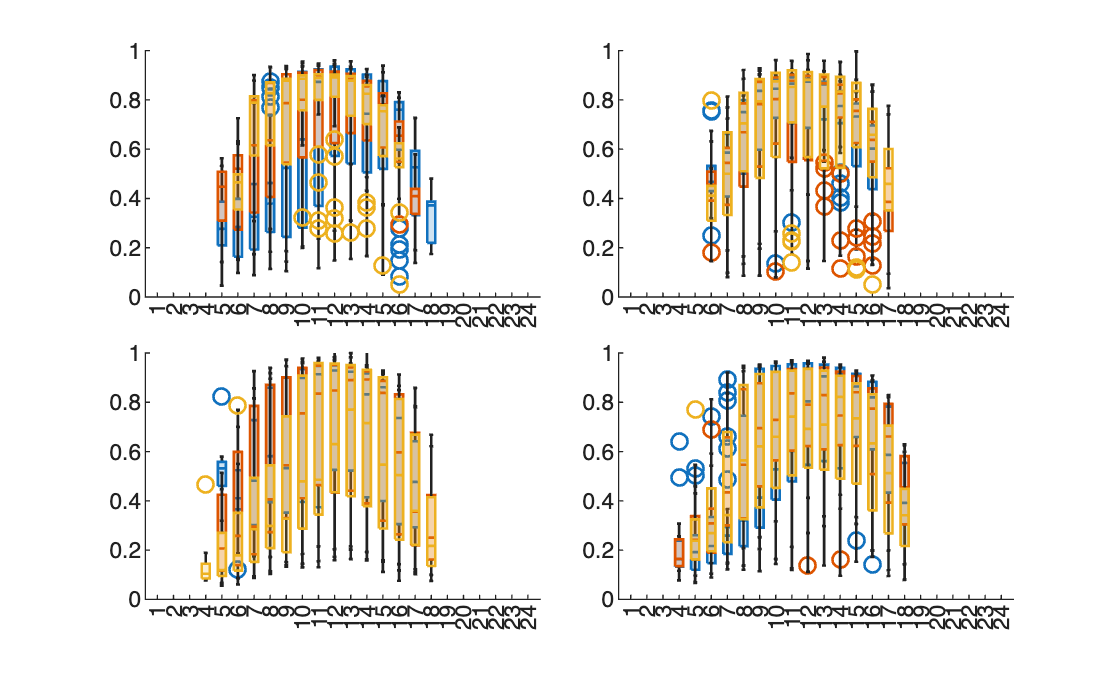

nexttile
hold on
boxchart(sepSW)
boxchart(octSW)
boxchart(novSW)
ylim([0 1])
hold off

nexttile
hold on
boxchart(decSW)
boxchart(janSW)
boxchart(febSW)
ylim([0 1])
hold off

nexttile
hold on
boxchart(marSW)
boxchart(aprSW)
boxchart(maySW)
ylim([0 1])
hold off

nexttile
hold on
boxchart(junSW)
boxchart(julSW)
boxchart(augSW)
ylim([0 1])
hold off

clf
winLWavg = mean([janLW, febLW, marLW],2,'omitmissing');
winSWavg = mean([janSW; febSW(1:28,:); marSW],3,'omitmissing');
sprLWavg = mean([aprLW, mayLW, junLW],2,'omitmissing');
sprSWavg = mean([aprSW; maySW; junSW],3,'omitmissing');
sumLWavg = mean([julLW, augLW, sepLW], 2,'omitmissing');
sumSWavg = mean([julSW; augSW; sepSW],3,'omitmissing');
falLWavg = mean([octLW, novLW, decLW], 2,'omitmissing');
falSWavg = mean([octSW; novSW; decSW],3,'omitmissing');

AnnualLWmean = mean([janLW,febLW,marLW,aprLW,mayLW,junLW,julLW,augLW,sepLW,octLW,novLW,decLW],"all",'omitmissing')

AnnualLWmean = 345.6072

AnnualLWstd = std([janLW,febLW,marLW,aprLW,mayLW,junLW,julLW,augLW,sepLW,octLW,novLW,decLW],[],"all",'omitmissing')

AnnualLWstd = 34.7114


AnnualSWmean = mean([janSW;febSW; marSW; aprSW; maySW; junSW; julSW; augSW; sepSW; octSW; novSW; decSW],'all','omitmissing')

AnnualSWmean = 0.5763

AnnualSWstd = std([janSW;febSW; marSW; aprSW; maySW; junSW; julSW; augSW; sepSW; octSW; novSW; decSW],[],'all','omitmissing')

AnnualSWstd = 0.2863



winLWavgmean = mean(winLWavg,'all','omitmissing')

winLWavgmean = 308.1281

winLWavgstd = std(winLWavg,[],'all','omitmissing')

winLWavgstd = 3.4717

winSWavgmean = mean(winSWavg,'all','omitmissing')

winSWavgmean = 0.6130

winSWavgstd = std(winSWavg,[],'all','omitmissing')

winSWavgstd = 0.2764


sprLWavgmean = mean(sprLWavg,'all','omitmissing')

sprLWavgmean = 366.7972

sprLWavgstd = std(sprLWavg,[],'all','omitmissing')

sprLWavgstd = 13.3070

sprSWavgmean = mean(sprSWavg,'all','omitmissing')

sprSWavgmean = 0.5018

sprSWavgstd = std(sprSWavg,[],'all','omitmissing')

sprSWavgstd = 0.3090


sumLWavgmean = mean(sumLWavg,'all','omitmissing')

sumLWavgmean = 384.4633

sumLWavgstd = std(sumLWavg,[],'all','omitmissing')

sumLWavgstd = 13.4314

sumSWavgmean = mean(sumSWavg,'all','omitmissing')

sumSWavgmean = 0.5560

sumSWavgstd = std(sumSWavg,[],'all','omitmissing')

sumSWavgstd = 0.2804


falLWavgmean = mean(falLWavg,'all','omitmissing')

falLWavgmean = 323.0402

falLWavgstd = std(falLWavg,[],'all','omitmissing')

falLWavgstd = 4.8555

falSWavgmean = mean(falSWavg,'all','omitmissing')

falSWavgmean = 0.6575

falSWavgstd = std(falSWavg,[],'all','omitmissing')

falSWavgstd = 0.2434


f = figure

f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9608 0.9608 0.9608]
    Position: [267 191 560 337.0317]
       Units: 'pixels'

  Show all properties


t4 = tiledlayout(2,2,'TileSpacing',"tight");

t11 = tiledlayout(t4,1,1);
t11.Layout.Tile = 1

t11 =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


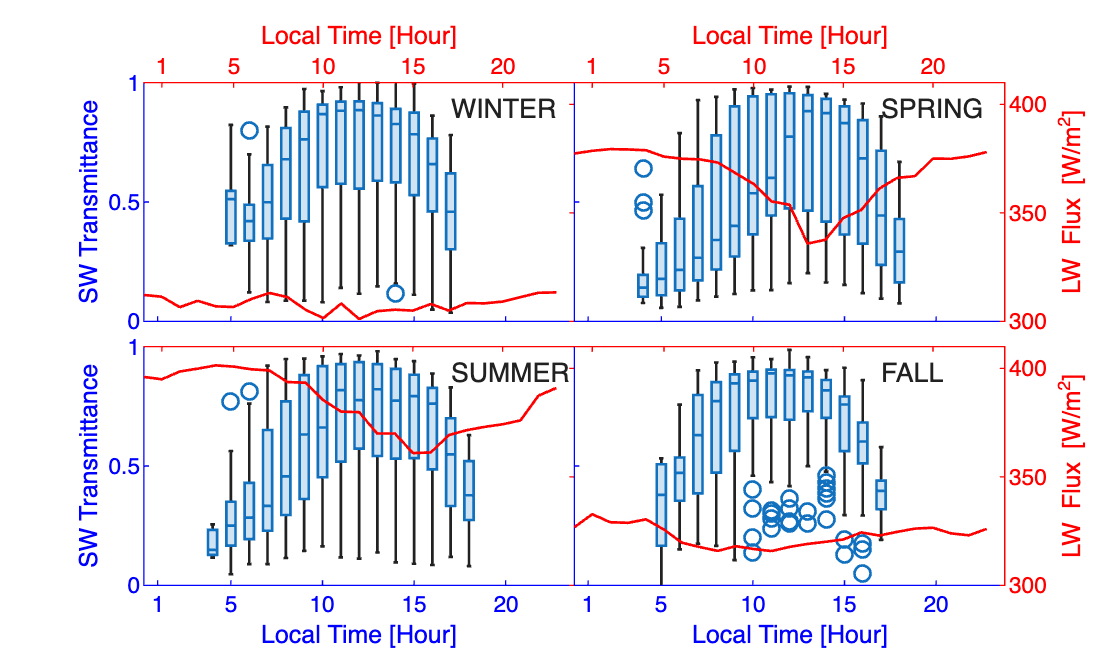

ax11 = axes(t11);
boxchart(ax11,winSWavg(:,1:23))
text(17, .9, 'WINTER')
ax11.XColor ='b';
ax11.YColor ='b';
ax11.Box = 'off';
ax11.XTick = ["1" "5" "10" "15" "20"];
ax11.YLim = [0 1];
ax11.XTickLabel = [];
ylabel(ax11,'SW Transmittance','Color','b')

xtickangle(ax11,0)
ax12 = axes(t11);
plot(ax12,djftime,winLWavg,'r','LineWidth',1)
ax12.XAxisLocation = 'Top';
ax12.XColor = 'r';
ax12.YAxisLocation = 'Right';
ax12.YColor = 'r';
ax12.YLim = [300 410];
ax12.XLim = [0 24];
ax12.XTick = [1 5 10 15 20];
ax12.Color = 'none';
ax12.Box = 'off';
ax12.YTickLabel = [];
xlabel(ax12,'Local Time [Hour]','Color','r')



t12 = tiledlayout(t4,1,1);
t12.Layout.Tile = 2;
ax21 = axes(t12);
boxchart(ax21,sprSWavg(:,1:23))
text(17, .9, 'SPRING')
ax21.XColor = 'b';
ax21.YColor = 'b';
ax21.Box = 'off';
ax21.YLim = [0 1];
ax21.XTick = ["1" "5" "10" "15" "20"];
ax21.XTickLabel = [];
ax21.YTickLabel = [];
xtickangle(ax21,0)
ax22 = axes(t12);
plot(ax22,mamtime,sprLWavg,'r','LineWidth',1)
ax22.XAxisLocation = 'Top';
ax22.XLim = [0 24];
ax22.XTick = [1 5 10 15 20];
ax22.XColor = 'r';
ax22.YAxisLocation = 'Right';
ax22.YColor = 'r';
ax22.YLim = [300 410];
ax22.Color = 'none';
ax22.Box = 'off';
xlabel(ax22,'Local Time [Hour]','Color','r')
ylabel(ax22,'LW Flux [W/m^2]')


t13 = tiledlayout(t4,1,1);
t13.Layout.Tile = 3;
ax31 = axes(t13);
boxchart(ax31,sumSWavg(:,1:23))
text(17, .9, 'SUMMER')
ax31.XColor = 'b';
ax31.YColor = 'b';
ax31.Box = 'off';
ax31.XTick = ["1" "5" "10" "15" "20"];
ax31.YLim = [0 1];
xtickangle(ax31,0)
xlabel(ax31,'Local Time [Hour]','Color','b')
ylabel(ax31,'SW Transmittance','Color','b')

ax32 = axes(t13);
plot(ax32,jjatime,sumLWavg,'r','LineWidth',1)
ax32.XAxisLocation = 'Top';
ax32.XLim = [0 24];
ax32.XTick = [1 5 10 15 20];
ax32.XColor = 'r';
ax32.YAxisLocation = 'Right';
ax32.YColor = 'r';
ax32.Color = 'none';
ax32.Box = 'off';
ax32.YLim = [300 410];
ax32.XTickLabel = [];
ax32.YTickLabel = [];


t14 = tiledlayout(t4,1,1);
t14.Layout.Tile = 4;
ax41 = axes(t14);
boxchart(ax41,falSWavg(:,1:23))
text(17, .9, 'FALL')
ax41.XColor = 'b';
ax41.YColor = 'b';
ax41.Box = 'off';
ax41.XTick = ["1" "5" "10" "15" "20"];
ax41.YLim = [0 1];
ax41.YTickLabel = [];
xtickangle(ax41,0)
xlabel(ax41,'Local Time [Hour]','Color','b')
ax42 = axes(t14);
hold on
plot(ax42,sontime,falLWavg,'r','LineWidth',1)
hold off
ax42.XAxisLocation = 'Top';
ax42.XLim = [0 24];
ax42.XColor = 'r';
ax42.XTick = [1 5 10 15 20];
ax42.XTickLabel = [];
ax42.YAxisLocation = 'Right';
ax42.YColor = 'r';
ax42.YLim = [300 410];
ax42.Color = 'none';
ax42.Box = 'off';
ylabel(ax42,'LW Flux [W/m^2]',Color='r')

clf
ta = tiledlayout(2,2,'TileSpacing','compact')

ta =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 2]
            Padding: 'loose'
        TileSpacing: 'compact'

  Show all properties


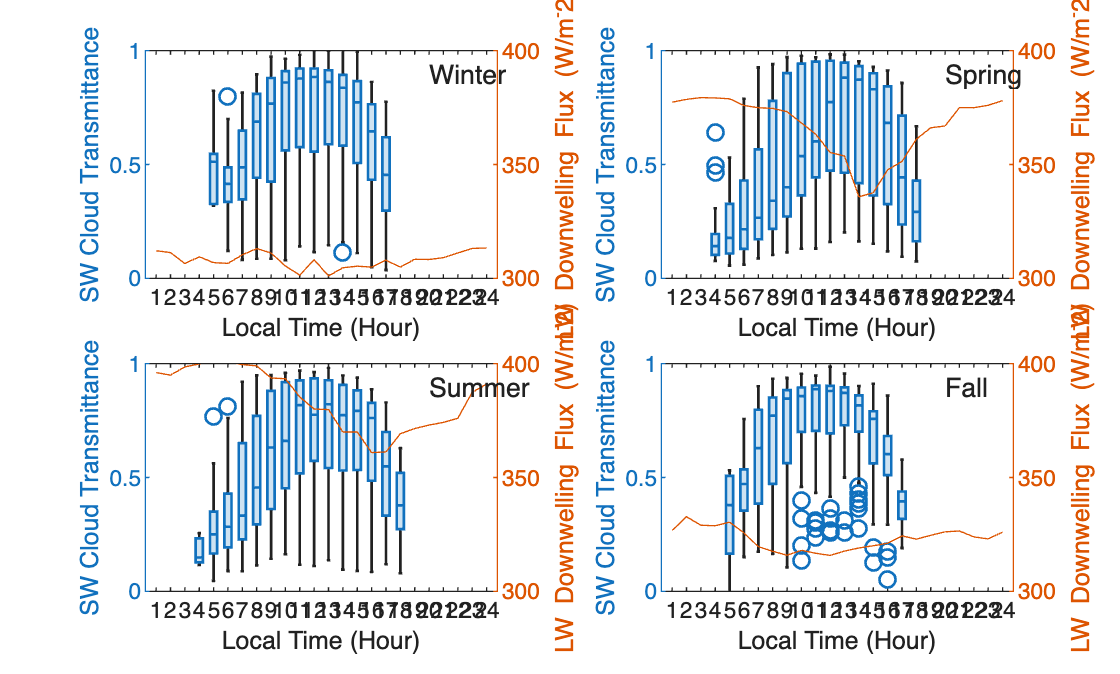

nexttile
yyaxis left
boxchart(winSWavg)
xtickangle(0)
ylim([0 1])
ylabel('SW Cloud Transmittance')
yyaxis right
plot(winLWavg)
ylim([300 400])
ylabel('LW Downwelling Flux (W/m^-2)')
xlabel('Local Time (Hour)')
text(20,390,'Winter')

nexttile
yyaxis left
boxchart(sprSWavg)
xtickangle(0)
ylim([0 1])
ylabel('SW Cloud Transmittance')
yyaxis right
plot(sprLWavg)
ylim([300 400])
ylabel('LW Downwelling Flux (W/m^-2)')
xlabel('Local Time (Hour)')
text(20,390,'Spring')


nexttile
yyaxis left
boxchart(sumSWavg)
xtickangle(0)
ylim([0 1])
ylabel('SW Cloud Transmittance')
yyaxis right
plot(sumLWavg)
ylim([300 400])
ylabel('LW Downwelling Flux (W/m^-2)')
xlabel('Local Time (Hour)')
text(20,390,'Summer')

nexttile
yyaxis left
boxchart(falSWavg)
ylim([0 1])
xtickangle(0)
ylabel('SW Cloud Transmittance')
yyaxis right
plot(falLWavg)
ylim([300 400])
ylabel('LW Downwelling Flux (W/m^-2)')
xlabel('Local Time (Hour)')
text(20,390,'Fall')

timecheck = SEP_SW_Boxplot{1,["Var1","Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10","Var11","Var12","Var13","Var14","Var15","Var16","Var17","Var18","Var19","Var20","Var21","Var22","Var23","Var24"]},

timecheck =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


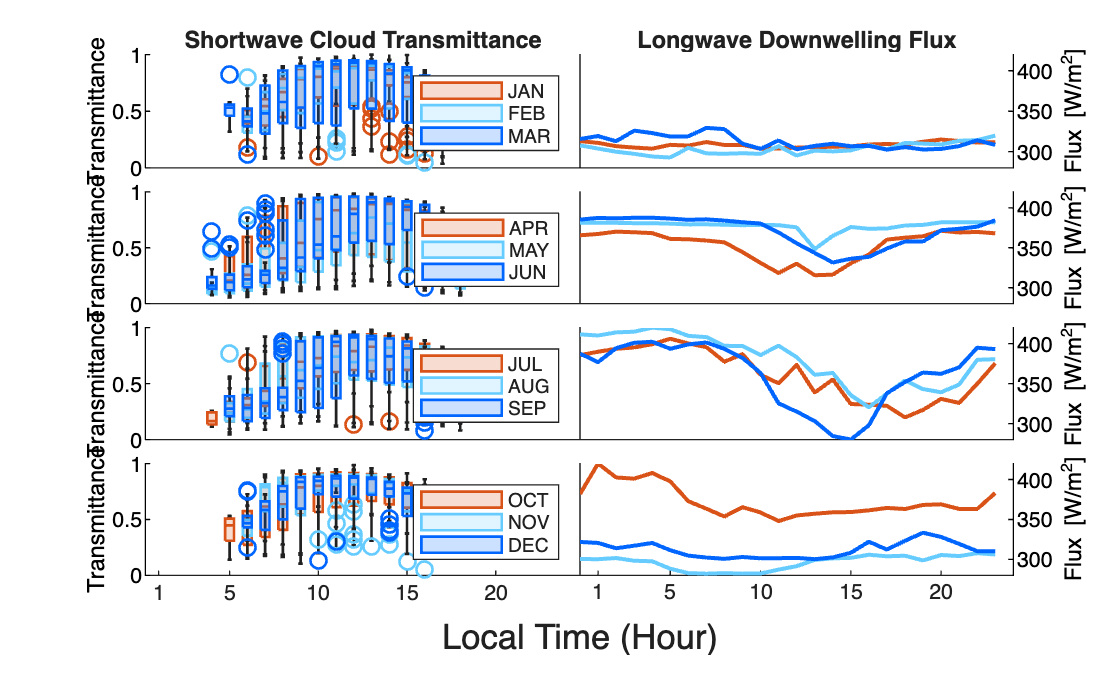


clf
t5 = tiledlayout(4,2,"TileSpacing","tight");
nexttile
hold on
boxchart(janSW,'BoxFaceColor','[0.8500, 0.3250, 0.0980 ]','MarkerColor','[0.8500, 0.3250, 0.0980 ]')
boxchart(febSW,'BoxFaceColor','#66CCFF','MarkerColor','#66CCFF')
boxchart(marSW,'BoxFaceColor','#0066FF','MarkerColor','#0066FF')
hold off
xtickangle(0)
title('Shortwave Cloud Transmittance')
legend('JAN','FEB','MAR')
ylim([0 1])
ax = gca;
ax.YColor = 'k';
xticks([])
ylabel('Transmittance')

nexttile
hold on
plot(djftime,janLW,'Color','[0.8500, 0.3250, 0.0980 ]','LineWidth',1.5)
plot(djftime,febLW,'Color','#66CCFF','LineWidth',1.5)
plot(djftime,marLW,'Color','#0066FF','LineWidth',1.5)
hold off
ylim([280 420])
title('Longwave Downwelling Flux')
yticks([])
yyaxis right
ylim([280 420])
ax = gca;
ax.YColor = 'k';
xlim([0 24])
xticks([1 5 10 15 20])
xticks([])
ylabel('Flux [W/m^2]')


nexttile
hold on
boxchart(aprSW,'BoxFaceColor','[0.8500, 0.3250, 0.0980 ]','MarkerColor','[0.8500, 0.3250, 0.0980 ]')
boxchart(maySW,'BoxFaceColor','#66CCFF','MarkerColor','#66CCFF')
boxchart(junSW,'BoxFaceColor','#0066FF','MarkerColor','#0066FF')
hold off
xtickangle(0)
legend("APR","MAY","JUN")
ylim([0 1])
ax = gca;
ax.YColor = 'k';
xticks([])
ylabel('Transmittance')


nexttile
hold on
plot(mamtime, aprLW,'Color','[0.8500, 0.3250, 0.0980 ]','LineWidth',1.5)
plot(mamtime, mayLW,'Color','#66CCFF','LineWidth',1.5)
plot(mamtime,junLW,'Color','#0066FF','LineWidth',1.5)
hold off
ylim([280 420])
yticks([])
yyaxis right
ylim([280 420])
ax = gca;
ax.YColor = 'k';
xlim([0 24])
xticks([1 5 10 15 20])
xticks([])
ylabel('Flux [W/m^2]')

nexttile
hold on
boxchart(julSW,'BoxFaceColor','[0.8500, 0.3250, 0.0980 ]','MarkerColor','[0.8500, 0.3250, 0.0980 ]')
boxchart(augSW,'BoxFaceColor','#66CCFF','MarkerColor','#66CCFF')
boxchart(sepSW,'BoxFaceColor','#0066FF','MarkerColor','#0066FF')
hold off
xtickangle(0)
legend('JUL','AUG','SEP')
ylim([0 1])
ax = gca;
ax.YColor = 'k';
xticks([])
ylabel('Transmittance')

nexttile
hold on
plot(jjatime,julLW,'Color','[0.8500, 0.3250, 0.0980 ]','LineWidth',1.5)
plot(jjatime,augLW,'Color','#66CCFF','LineWidth',1.5)
plot(jjatime,sepLW,'Color','#0066FF','LineWidth',1.5)
hold off
yticks([])
yyaxis right
ylim([280 420])
ax = gca;
ax.YColor = 'k';
xlim([0 24])
xticks([1 5 10 15 20])
xticks([])
ylabel('Flux [W/m^2]')


nexttile
hold on
boxchart(octSW,'BoxFaceColor','[0.8500, 0.3250, 0.0980 ]','MarkerColor','[0.8500, 0.3250, 0.0980 ]')
boxchart(novSW,'BoxFaceColor','#66CCFF','MarkerColor','#66CCFF')
boxchart(decSW,'BoxFaceColor','#0066FF','MarkerColor','#0066FF')
hold off
xtickangle(0)
xticks(["1" "5" "10" "15" "20" ])
legend('OCT','NOV','DEC')
ylim([0 1])
ax = gca;
ax.YColor = 'k';
ylabel('Transmittance')

nexttile
hold on
plot(sontime,octLW,'Color','[0.8500, 0.3250, 0.0980 ]','LineWidth',1.5)
plot(sontime,novLW,'Color','#66CCFF','LineWidth',1.5)
plot(sontime,decLW,'Color','#0066FF','LineWidth',1.5)
hold off
yticks([])
yyaxis right
ylim([280 420])
ax = gca;
ax.YColor = 'k';
xlim([0 24])
xticks([1 5 10 15 20])
ylabel('Flux [W/m^2]')


xlabel(t5,'Local Time (Hour)','FontSize',13)

clf
ncdisp("arscl_echomask_hourly.nc");

Source:
           /Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/fwdcirclingbacktoepcapeoverview/arscl_echomask_hourly.nc
Format:
           netcdf4
Global Attributes:
           datastream  = 'epcarsclkazr1kolliasM1.c1'
           source_dir  = '/Users/vghate/Desktop/tryout/data/arscl_echomask'
           description = 'Hourly echo fraction profiles. echo_fraction = sum(flag>=2) / sum(flag>=1). Flag: 0=both missing, 1=clear, 2=radar+lidar, 3=radar only, 4=lidar only, 5=radar+lidar_missing, 6=lidar+radar_missing.'
Dimensions:
           time   = 8809
           height = 596
Variables:
    time         
           Size:       8809x1
           Dimensions: time
           Datatype:   double
           Attributes:
                       units     = 'seconds since 1970-01-01 00:00:00 UTC'
                       long_name = 'Hour start time (UTC)'
    height       
           Size:       596x1
           Dimensions: height
           Datatype:   single
           Attributes:
        

time = ncread("arscl_echomask_hourly.nc","time");
d = datetime(time, 'ConvertFrom',"epochtime", "Epoch", datetime(1970,1,1,00,00,00),"TicksPerSecond",1, "Format","default",'TimeZone','UTC');
d = datetime(d,'TimeZone','America/Los_Angeles')

d = 8809×1 datetime array
   14-Feb-2023 16:00:00
   14-Feb-2023 17:00:00
   14-Feb-2023 18:00:00
   14-Feb-2023 19:00:00
   14-Feb-2023 20:00:00
   14-Feb-2023 21:00:00
   14-Feb-2023 22:00:00
   14-Feb-2023 23:00:00
   15-Feb-2023 00:00:00
   15-Feb-2023 01:00:00
   15-Feb-2023 02:00:00
   15-Feb-2023 03:00:00
   15-Feb-2023 04:00:00
   15-Feb-2023 05:00:00
   15-Feb-2023 06:00:00
   15-Feb-2023 07:00:00
   15-Feb-2023 08:00:00
   15-Feb-2023 09:00:00
   15-Feb-2023 10:00:00
   15-Feb-2023 11:00:00
   15-Feb-2023 12:00:00
   15-Feb-2023 13:00:00
   15-Feb-2023 14:00:00
   15-Feb-2023 15:00:00
   15-Feb-2023 16:00:00
   15-Feb-2023 17:00:00
   15-Feb-2023 18:00:00
   15-Feb-2023 19:00:00
   15-Feb-2023 20:00:00
   15-Feb-2023 21:00:00


dateshift(d,"end","hour")

ans = 8809×1 datetime array
   14-Feb-2023 17:00:00
   14-Feb-2023 18:00:00
   14-Feb-2023 19:00:00
   14-Feb-2023 20:00:00
   14-Feb-2023 21:00:00
   14-Feb-2023 22:00:00
   14-Feb-2023 23:00:00
   15-Feb-2023 00:00:00
   15-Feb-2023 01:00:00
   15-Feb-2023 02:00:00
   15-Feb-2023 03:00:00
   15-Feb-2023 04:00:00
   15-Feb-2023 05:00:00
   15-Feb-2023 06:00:00
   15-Feb-2023 07:00:00
   15-Feb-2023 08:00:00
   15-Feb-2023 09:00:00
   15-Feb-2023 10:00:00
   15-Feb-2023 11:00:00
   15-Feb-2023 12:00:00
   15-Feb-2023 13:00:00
   15-Feb-2023 14:00:00
   15-Feb-2023 15:00:00
   15-Feb-2023 16:00:00
   15-Feb-2023 17:00:00
   15-Feb-2023 18:00:00
   15-Feb-2023 19:00:00
   15-Feb-2023 20:00:00
   15-Feb-2023 21:00:00
   15-Feb-2023 22:00:00


height = ncread("arscl_echomask_hourly.nc","height");
echo_fraction = ncread("arscl_echomask_hourly.nc", "echo_fraction");

ncdisp("epcceil_hourly_cbh.nc");

Source:
           /Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/fwdcirclingbacktoepcapeoverview/epcceil_hourly_cbh.nc
Format:
           netcdf4
Global Attributes:
           datastream  = 'epcceil10mM1.b1'
           source_dir  = '/Users/vghate/Desktop/epcape/ceil'
           description = 'Hourly BL cloud statistics from EPCAPE ceilometer. bl_cbh: mean CBH of BL-cloudy samples. bl_cloud_fraction: fraction of QC-valid samples with BL cloud detected.'
Dimensions:
           time = 8809
Variables:
    time             
           Size:       8809x1
           Dimensions: time
           Datatype:   double
           Attributes:
                       units     = 'seconds since 1970-01-01 00:00:00 UTC'
                       long_name = 'Hour start time (UTC)'
    bl_cbh           
           Size:       8809x1
           Dimensions: time
           Datatype:   single
           Attributes:
                       _FillValue = NaN
                       long_name  = 'Hourly mean 

time2 = ncread("epcceil_hourly_cbh.nc","time");
d2 = datetime(time, 'ConvertFrom',"epochtime", "Epoch", datetime(1970,1,1,00,00,00),"TicksPerSecond",1, "Format","default",'TimeZone','UTC');
d2 = datetime(d,'TimeZone','America/Los_Angeles')

d2 = 8809×1 datetime array
   14-Feb-2023 16:00:00
   14-Feb-2023 17:00:00
   14-Feb-2023 18:00:00
   14-Feb-2023 19:00:00
   14-Feb-2023 20:00:00
   14-Feb-2023 21:00:00
   14-Feb-2023 22:00:00
   14-Feb-2023 23:00:00
   15-Feb-2023 00:00:00
   15-Feb-2023 01:00:00
   15-Feb-2023 02:00:00
   15-Feb-2023 03:00:00
   15-Feb-2023 04:00:00
   15-Feb-2023 05:00:00
   15-Feb-2023 06:00:00
   15-Feb-2023 07:00:00
   15-Feb-2023 08:00:00
   15-Feb-2023 09:00:00
   15-Feb-2023 10:00:00
   15-Feb-2023 11:00:00
   15-Feb-2023 12:00:00
   15-Feb-2023 13:00:00
   15-Feb-2023 14:00:00
   15-Feb-2023 15:00:00
   15-Feb-2023 16:00:00
   15-Feb-2023 17:00:00
   15-Feb-2023 18:00:00
   15-Feb-2023 19:00:00
   15-Feb-2023 20:00:00
   15-Feb-2023 21:00:00


bl_cbh = ncread("epcceil_hourly_cbh.nc",'bl_cbh');

sprcbheight = nan(368,24);
for i = 0:24
    heldsize = size(bl_cbh(hour(d2) == i & month(d2) >= 4 & month(d2) <= 6),1);
    sprcbheight(1:heldsize,i+1) = bl_cbh(hour(d2) == i & month(d2) >= 4 & month(d2) <= 6);
end


ncdisp("epcmwrret_turnM1_hourly_averages.nc")

Source:
           /Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/fwdcirclingbacktoepcapeoverview/epcmwrret_turnM1_hourly_averages.nc
Format:
           netcdf4
Global Attributes:
           description = 'Hourly averages of epcmwrret2turnM1.c1 (EPCAPE, La Jolla CA)'
           campaign    = 'EPCAPE'
           datastream  = 'epcmwrret2turnM1.c1'
           created     = '2026-02-19 21:09:50'
Dimensions:
           time = 7913
Variables:
    time                
           Size:       7913x1
           Dimensions: time
           Datatype:   double
           Attributes:
                       units     = 'seconds since 1970-01-01 00:00:00 UTC'
                       long_name = 'hour start time (UTC)'
    phys_lwp            
           Size:       7913x1
           Dimensions: time
           Datatype:   single
           Attributes:
                       _FillValue = NaN
                       units      = 'g/m^2'
                       long_name  = 'Physically-retrieved liqu

time7913 = ncread("epcmwrret_turnM1_hourly_averages.nc","time");
d7913 = datetime(time7913, 'ConvertFrom',"epochtime", "Epoch", datetime(1970,1,1,00,00,00),"TicksPerSecond",1, "Format","default",'TimeZone','UTC');
d7913 = datetime(d7913,'TimeZone','America/Los_Angeles');

lwp7913 = ncread("epcmwrret_turnM1_hourly_averages.nc","phys_lwp");
sprlwpbox = nan(330,24);
for i = 0:24
    heldsize = size(lwp7913(hour(d7913) == i & month(d7913) >= 4 & month(d7913) <= 6),1);
    sprlwpbox(1:heldsize,i+1) = lwp7913(hour(d7913) == i & month(d7913) >= 4 & month(d7913) <= 6);
end

tbl = readtable("EPCAPE_CTH_CBH_PBLH_SChellappan_LaRC.csv");

monthOrder = {'1','2','3','4','5','6','7','8','9','10','11','12'};


timesche= tbl{:,'Time'};
tbl.("month") = month(timesche) 

tbl = 2937×7 table
           Time            GOES18_CTH    KAZR_CTH    CEIL_CBH    PBLH_THERMO    PBLH_MPL    month
    ___________________    __________    ________    ________    ___________    ________    _____

    2023-03-01 01:30:21      420.85          940      876.55         1486        1151.7       3  
    2023-03-01 03:00:21      984.01       1514.2      978.22         1491        1291.6       3  
    2023-03-01 11:00:21      1136.6       1241.7      844.53         1438        1041.8       3  
    2023-03-01 11:30:21      1087.2       1066.6      691.67         1539        881.89       3  
    2023-03-01 16:30:21      1677.8       1290.1      1477.3         1539        821.93       3  
    2023-03-01 17:30:21      1305.2       1643.6      87

%+ (year(timesche)-2023).*12

tbl2 = readtable("BL_Depth.csv");
timesche2= tbl2{:,'Time'};
tbl2.("month") = month(timesche2)

tbl2 = 1098×4 table
            Time            Depth     z_concen    month
    ____________________    ______    ________    _____

    15-Feb-2023 09:00:00     907.5        NaN       2  
    15-Feb-2023 21:00:00     367.5     416.25       2  
    16-Feb-2023 09:18:00     397.5        NaN       2  
    16-Feb-2023 21:00:00     337.5        NaN       2  
    17-Feb-2023 09:02:00     442.5        NaN       2  
    17-Feb-2023 21:02:00     277.5        NaN       2  
    18-Feb-2023 09:00:00     727.5        NaN       2  
    18-Feb-2023 21:00:00     337.5        NaN       2  
    19-Feb-2023 09:00:00     727.5     761.25       2  
    19-Feb-2023 21:00:00     397.5     423.75       2  
    20-Feb-2023 09:00:00     292.5        NaN       2  
    20-Feb-2023 21:00:00     322.5     363.75       2  
    21-Feb-2023 09:00:00     457.5        NaN       2  
   

%+ (year(timesche2)-2023).*12;

tbl3 = readtable("EPCAPE_sonde_LCL.csv");
timesche3 = tbl3{:,'time'};
tbl3.("month") = month(timesche3)

tbl3 = 35041×3 table
            time             LCL      month
    ____________________    ______    _____

    15-Feb-2023 00:00:00    1212.4      2  
    15-Feb-2023 00:15:00    1215.4      2  
    15-Feb-2023 00:30:00    1218.5      2  
    15-Feb-2023 00:45:00    1221.5      2  
    15-Feb-2023 01:00:00    1224.5      2  
    15-Feb-2023 01:15:00    1227.5      2  
    15-Feb-2023 01:30:00    1230.6      2  
    15-Feb-2023 01:45:00    1233.6      2  
    15-Feb-2023 02:00:00    1236.6      2  
    15-Feb-2023 02:15:00    1239.6      2  
    15-Feb-2023 02:30:00    1242.6      2  
    15-Feb-2023 02:45:00    1245.7      2  
    15-Feb-2023 03:00:00    1248.7      2  
    15-Feb-2023 03:15:00    1251.7      2  
    15-Feb-2023 03:30:00    1254.7      2  
    15-Feb-2023 03:45:00    1257.7      2  


%+ (year(timesche3)-2023).*12;
tbl.month;
tbl2.month;
tbl3.month;

newmonth = cat(1,tbl.month,tbl.month,tbl.month,tbl.month, tbl2.month,tbl3.month, tbl.month);
newdata = cat(1,tbl.GOES18_CTH,tbl.KAZR_CTH,tbl.PBLH_THERMO,tbl.PBLH_MPL,tbl2.Depth,tbl3.LCL,tbl.CEIL_CBH);
index = strings(14685+1098+35041,1);
index(1:2937) = "1. GOES18 CTH";
index(2938:2937+2937) = "2. KAZR CTH";
index(2937+2937:2937+2937+2937) = "3. PBLH THERMO";
index(2937+2937+2937:2937+2937+2937+2937) = "4. PBLH MPL";
index(2937+2937+2937+2937:2937+2937+2937+2937+1098)  = "5. BL DEPTH";
index(2937+2937+2937+2937+1098:2937+2937+2937+2937+1098+35041) = "6. LCL";
index(2937+2937+2937+2937+1098+35041:2937+2937+2937+2937+2937+1098+35041) = "7. CEIL CBH";

newmonth = categorical(string(newmonth),monthOrder)

newmonth = 50824×1 categorical array
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 
     3 


var = tbl.CEIL_CBH

var = 1.0e+03 *

    0.8766
    0.9782
    0.8445
    0.6917
    1.4773
    0.8778
    1.6550
    1.0732
    0.8521
    1.2244
    1.1383
    1.1350
    0.8949
    0.7134
    0.8337



win = tbl.month >= 1 & tbl.month <= 3;
spr = tbl.month >= 4 & tbl.month <= 6;
sum = tbl.month >= 7 & tbl.month <= 9;
fal = tbl.month >= 10 & tbl.month <= 12;


mean(var,'omitmissing')

ans = 661.6665

std(var,'omitmissing')

ans = 316.3159


mean(var(spr),'omitmissing')

ans = 619.6777

std(var(spr),'omitmissing')

ans = 270.1084


mean(var(sum),'omitmissing')

ans = 553.6578

std(var(sum),'omitmissing')

ans = 254.1788


mean(var(fal),'omitmissing')

ans = 836.4547

std(var(fal),'omitmissing')

ans = 388.6054


mean(var(win),'omitmissing')

ans = 928.8396

std(var(win),'omitmissing')

ans = 362.4168


clf
sprechomap = zeros(596,24);
for i = 0:24
    sprechomap(:,i+1) = mean(echo_fraction(:,hour(d) == i & month(d) <= 6 & month(d) >= 4),2,'omitmissing');

end

echospr = tiledlayout(4,4,'TileSpacing','tight');

nexttile(echospr,1,[2 1])
yyaxis right
boxplot(sprcbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980],'Widths',0.3)

xlim([0.5 24.5])
ylim([0 3000])
xticklabels([])
yticklabels([])

yyaxis left
pcolor(0.5:24.5,height,sprechomap,'EdgeColor','none')
colormap('sky')
ylim([0 3000])
title('Spring')
ylabel('Height [m]')

nexttile(echospr,9,[1 1])
boxplot(sprlwpbox(:,1:24),'Symbol','')

xticklabels([])
ylabel('Liquid Water Path [g/m^2]')
ylim([0 500])

nexttile(echospr,13,[1,1])
yyaxis right
boxplot(sprSWavg,'Symbol','','Colors',[0, 0.4470, 0.7410])

yticklabels([])
xticklabels(["0" "" "" "" "" "5" "" "" "" "" "10" "" "" "" "" "15" "" "" "" "" "20" "" "" "23"])
xtickangle(0)
ylim([0 1])

yyaxis left
plot(mamtime+1,sprLWavg,Color=[0.6350, 0.0780, 0.1840])
ylabel('LW Flux',Color=[0.6350, 0.0780, 0.1840])
ax = gca;
ax.YColor = [0.6350, 0.0780, 0.1840];
ylim([300 410])

xlabel('Local Time [Hour]')
sumcbheight = nan(368,24);
for i = 0:24
    heldsize = size(bl_cbh(hour(d2) == i & month(d2) >= 7 & month(d2) <= 9),1);
    sumcbheight(1:heldsize,i+1) = bl_cbh(hour(d2) == i & month(d2) >= 7 & month(d2) <= 9);
end




sumlwpbox = nan(330,24);
for i = 0:24
    heldsize = size(lwp7913(hour(d7913) == i & month(d7913) >= 7 & month(d7913) <= 9),1);
    sumlwpbox(1:heldsize,i+1) = lwp7913(hour(d7913) == i & month(d7913) >= 7 & month(d7913) <= 9);
end


sumechomap = zeros(596,24);
for i = 0:24
    sumechomap(:,i+1) = mean(echo_fraction(:,hour(d) == i & month(d) >= 7 & month(d) <= 9),2,'omitmissing');

end

%echosum = tiledlayout(4,2,'TileSpacing','compact');

nexttile(echospr,2,[2 1])
yyaxis right
boxplot(sumcbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980],'Widths',0.3)

ylim([0 3000])
xlim([0.5 24.5])
xticklabels([])
yticklabels([])

yyaxis left
pcolor(0.5:24.5,height,sumechomap,'EdgeColor','none')
ylim([0 3000])
colormap('sky')
title('Summer')
yticklabels([])

nexttile(echospr,10,[1 1])
boxplot(sumlwpbox(:,1:24),'Symbol','')

xticklabels([])
ylim([0 500])
yticklabels([])

nexttile(echospr,14,[1,1])
yyaxis right
boxplot(sumSWavg,'Symbol','','Colors',[0, 0.4470, 0.7410])

xticklabels(["0" "" "" "" "" "5" "" "" "" "" "10" "" "" "" "" "15" "" "" "" "" "20" "" "" "23"])
xtickangle(0)
yticklabels([])
ylim([0 1])

yyaxis left
plot(mamtime+1,sumLWavg,Color=[0.6350, 0.0780, 0.1840])
yticklabels([])
ylim([300 410])

xlabel('Local Time [Hour]')


falcbheight = nan(368,24);
for i = 0:24
    heldsize = size(bl_cbh(hour(d2) == i & month(d2) >= 10 & month(d2) <= 12),1);
    falcbheight(1:heldsize,i+1) = bl_cbh(hour(d2) == i & month(d2) >= 10 & month(d2) <= 12);
end



lwp7913 = ncread("epcmwrret_turnM1_hourly_averages.nc","phys_lwp");
fallwpbox = nan(330,24);
for i = 0:24
    heldsize = size(lwp7913(hour(d7913) == i & month(d7913) >= 10 & month(d7913) <= 12),1);
    fallwpbox(1:heldsize,i+1) = lwp7913(hour(d7913) == i & month(d7913) >= 10 & month(d7913) <= 12);
end


falechomap = zeros(596,24);
for i = 0:24
    falechomap(:,i+1) = mean(echo_fraction(:,hour(d) == i & month(d) >= 10 & month(d) <= 12),2,'omitmissing');

end


nexttile(echospr,3,[2 1])
yyaxis right
boxplot(falcbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980],'Widths',0.3)

ylim([0 3000])
xlim([0.5 24.5])
xticklabels([])
yticklabels([])

yyaxis left
pcolor(0.5:24.5,height,falechomap,'EdgeColor','none')
ylim([0 3000])
colormap('sky')
title('Fall')
yticklabels([])

nexttile(echospr,11,[1 1])
boxplot(fallwpbox(:,1:24),'Symbol','','Colors',[0, 0.4470, 0.7410])

xticklabels([])
ylim([0 500])
yticklabels([])


nexttile(echospr,15,[1,1])
yyaxis right
boxplot(falSWavg,'Symbol','','Colors',[0, 0.4470, 0.7410])

xticklabels(["0" "" "" "" "" "5" "" "" "" "" "10" "" "" "" "" "15" "" "" "" "" "20" "" "" "23"])
xtickangle(0)
yticklabels([])
ylim([0 1])


yyaxis left
plot(mamtime+1,falLWavg, Color=[0.6350, 0.0780, 0.1840])
ylim([300 410])
yticklabels([])

xlabel('Local Time [Hour]')

wincbheight = nan(368,24);
for i = 0:24
    heldsize = size(bl_cbh(hour(d2) == i & month(d2) >= 1 & month(d2) <= 3),1);
    wincbheight(1:heldsize,i+1) = bl_cbh(hour(d2) == i & month(d2) >= 1 & month(d2) <= 3);
end


lwp7913 = ncread("epcmwrret_turnM1_hourly_averages.nc","phys_lwp");
winlwpbox = nan(330,24);
for i = 0:24
    heldsize = size(lwp7913(hour(d7913) == i & month(d7913) >= 1 & month(d7913) <= 3),1);
    winlwpbox(1:heldsize,i+1) = lwp7913(hour(d7913) == i & month(d7913) >= 1 & month(d7913) <= 3);
end


winechomap = zeros(596,24);
for i = 0:24
    winechomap(:,i+1) = mean(echo_fraction(:,hour(d) == i & month(d) >= 1 & month(d) <= 3),2,'omitmissing');

end


nexttile(echospr,4,[2 1])
yyaxis right
boxplot(wincbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980],'Widths',0.3)

ylabel('Cloud Base Height')
xlim([0.5 24.5])
xticklabels([])
yticklabels([])
ylim([0 3000])

yyaxis left
pcolor(0.5:24.5,height,winechomap,'EdgeColor','none')
ylim([0 3000])
colormap('sky')
c = colorbar;
clim([0 0.5])
ylim([0 3000])
title('Winter')
yticklabels([])

ylabel(c, "Echo Fraction")

nexttile(echospr,12,[1 1])
boxplot(winlwpbox(:,1:24),'Symbol','')

xticklabels([])
yticklabels([])
ylim([0 500])

nexttile(echospr,16,[1,1])
yyaxis right
boxplot(winSWavg,'Symbol','','Colors',[0, 0.4470, 0.7410])

ylabel('SW Trasmittance','Color',[0, 0.4470, 0.7410])
ax = gca;
ax.YColor = '[0, 0.4470, 0.7410]'

ax =   Axes with properties:

    YAxisLocation: 'right'
            YAxis: [2×1 NumericRuler]
             YLim: [-0.1044 1.0928]
             XLim: [0.5000 24.5000]
           XScale: 'linear'
           YScale: 'linear'
         Position: [0.6779 0.1150 0.1459 0.1741]
            Units: 'normalized'

  Show all properties


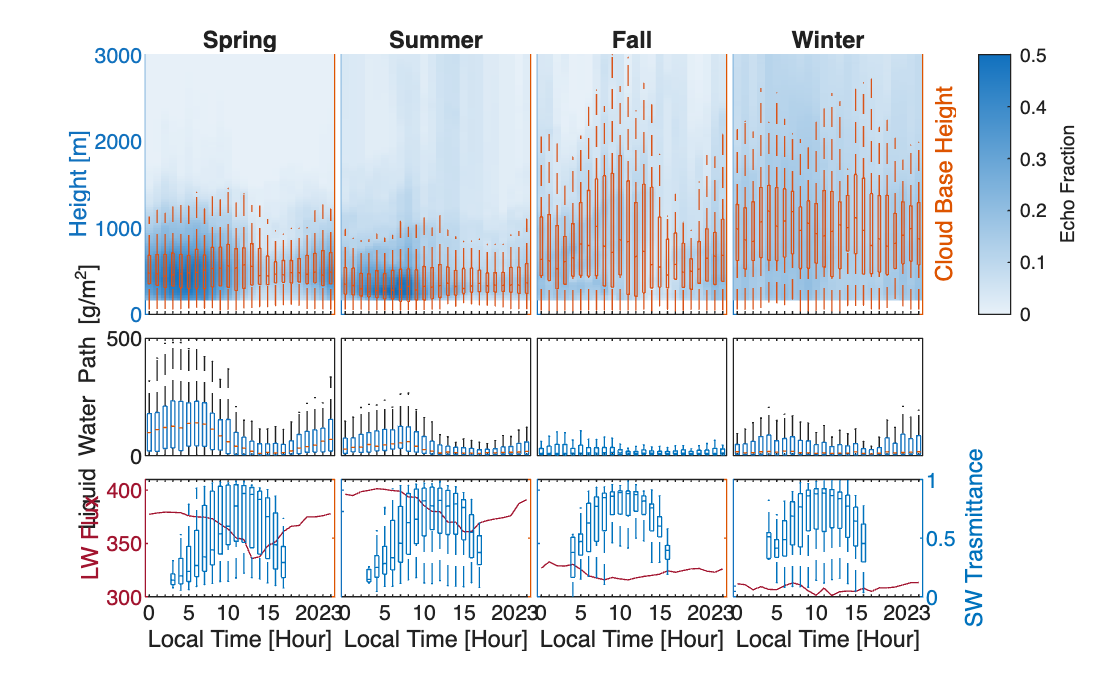

xticklabels(["0" "" "" "" "" "5" "" "" "" "" "10" "" "" "" "" "15" "" "" "" "" "20" "" "" "23"])
xtickangle(0)
ylim([0 1])

yyaxis left
plot(mamtime+1,winLWavg,Color=[0.6350, 0.0780, 0.1840])
yticklabels([])
ylim([300 410])

xlabel('Local Time [Hour]')

sprsumcbheight = nan(368,24);
for i = 0:24
    heldsize = size(bl_cbh(hour(d2) == i & month(d2) >= 4 & month(d2) <= 9),1);
    sprsumcbheight(1:heldsize,i+1) = bl_cbh(hour(d2) == i & month(d2) >= 4 & month(d2) <= 9);
end



lwp7913 = ncread("epcmwrret_turnM1_hourly_averages.nc","phys_lwp");
sprsumlwpbox = nan(330,24);
for i = 0:24
    heldsize = size(lwp7913(hour(d7913) == i & month(d7913) >= 4 & month(d7913) <= 9),1);
    sprsumlwpbox(1:heldsize,i+1) = lwp7913(hour(d7913) == i & month(d7913) >= 4 & month(d7913) <= 9);
end

clf
sprsumechomap = zeros(596,24);
for i = 0:24
    sprsumechomap(:,i+1) = mean(echo_fraction(:,hour(d) == i & month(d) >= 4 & month(d) <= 9),2,'omitmissing');

end

echosprsum = tiledlayout(4,1,'TileSpacing','Compact');

nexttile(echosprsum,[2 1])
yyaxis right
boxplot(sprsumcbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980])

ylabel('Cloud Base Height')
xlim([0.5 24.5])
xticklabels([])
yticklabels([])

yyaxis left
pcolor(0.5:24.5,height,sprsumechomap,'EdgeColor','none')
colormap('sky')
c = colorbar;
clim([0 0.5])
ylim([0 3000])
title('Spring Summer Echo Plot')
ylabel('Height [m]')
ylabel(c, "Echo Fraction")

nexttile(echosprsum,[1 1])
boxplot(sprsumlwpbox(:,1:24),'Symbol','')

xticklabels([])
ylabel('Liquid Water Path [g/m^2]')
ylim([0 500])

nexttile(echosprsum,[1,1])
yyaxis right
boxplot(mean(cat(3,sumSWavg, sprSWavg),3),'Symbol','')

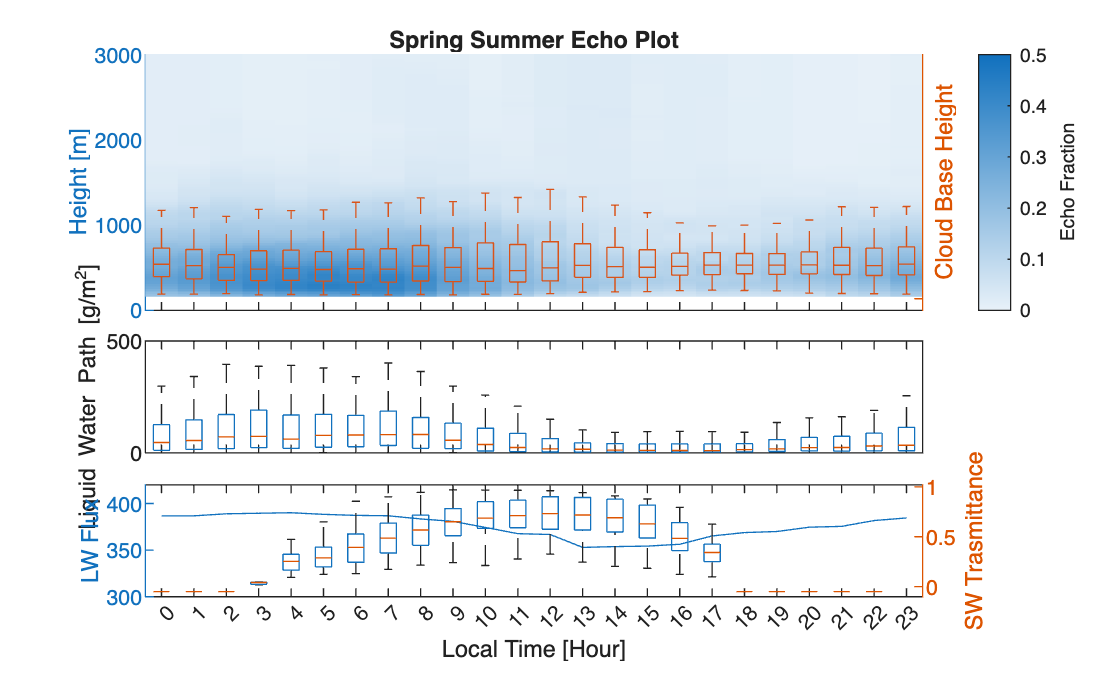

ylabel('SW Trasmittance')
xticklabels(["0" "1" "2" "3" "4" "5" "6" "7" "8" "9" "10" "11" "12" "13" "14" "15" "16" "17" "18" "19" "20" "21" "22" "23"])

yyaxis left
plot(mamtime+1,mean([sumLWavg sprLWavg],2))
ylabel('LW Flux')
ylim([300 420])

xlabel('Local Time [Hour]')


yearlycbheight = nan(500,12);
for i = 1:12
    heldsize = size(bl_cbh(month(d2) == i ),1);
    yearlycbheight(1:heldsize,i+1) = bl_cbh(month(d2) == i );
end
%for i = 1:2
%    heldsize = size(bl_cbh(month(d2) == i),1);
%    yearlycbheight(1:heldsize,i+11) = bl_cbh(month(d2) == i );
%end

yearlylwpbox = nan(500,12);
for i = 1:12
    heldsize = size(lwp7913(month(d7913) == i),1);
    yearlylwpbox(1:heldsize,i+1) = lwp7913(month(d7913) == i );
end

mean(yearlylwpbox,'all','omitmissing')

ans = 56.3925

std(yearlylwpbox,[],'all','omitmissing')

ans = 127.6987

mean(yearlylwpbox(:,4:6),'all','omitmissing')

ans = 92.2067

std(yearlylwpbox(:,4:6),[],'all','omitmissing')

ans = 161.2325


mean(yearlylwpbox(:,7:9),'all','omitmissing')

ans = 58.5060

std(yearlylwpbox(:,7:9),[],'all','omitmissing')

ans = 118.2163


mean(yearlylwpbox(:,10:12),'all','omitmissing')

ans = 42.3573

std(yearlylwpbox(:,10:12),[],'all','omitmissing')

ans = 100.1877


mean(yearlylwpbox(:,1:3),'all','omitmissing')

ans = 33.0283

std(yearlylwpbox(:,1:3),[],'all','omitmissing')

ans = 91.8912


%for i = 1:2
%    heldsize = size(lwp7913(month(d7913) == i ),1);
%    yearlylwpbox(1:heldsize,i+11) = lwp7913(month(d7913) == i);
%end

yearlyechomap = zeros(596,12);
clear mean
for i = 1:12
        yearlyechomap(:,i+1) = mean(echo_fraction(:,month(d) == i),2,'omitmissing');
end

%for i = 1:2
%    yearlyechomap(:,i+11) = mean(echo_fraction(:,month(d) == i & year(d) == 2024),2,'omitmissing');
%end

echoyearly = tiledlayout(7,1,'TileSpacing','Tight');

nexttile(echoyearly,1,[2 1])
b = boxchart(newmonth,newdata,'GroupByColor',index,'MarkerStyle','none','Notch','on','WhiskerLineStyle','none');
b(1).BoxFaceColor = [0.129, 0.408, 0.91];
b(2).BoxFaceColor = [0.129, 0.635, 0.91];
b(3).BoxFaceColor = [0.129, 0.91, 0.4];
b(4).BoxFaceColor = [0.098, 0.702, 0.224];
b(5).BoxFaceColor = [0.871, 0.855, 0.118];
b(6).BoxFaceColor = [0.702, 0.098, 0.4];
b(7).BoxFaceColor = [0.871, 0.118, 0.18];

lgd = legend("\color{white}1\color{black}GOES18 CTH","\color{white}2\color{black}KAZRCTH","\color{white}3\color{black}PBLH THERMO","\color{white}4\color{black}PBLH MPL","\color{white}5\color{black}BL DEPTH","\color{white}6\color{black}SONDE LCL","\color{white}7\color{black}CEIL CBH")

lgd =   Legend (\color{white}1\color{black}GOES18 CTH, \color{white}2\color{black}KAZRCTH, \color{white}3\color{black}PBLH THERMO, \color{white}4\color{black}PBLH MPL, \color{white}5\color{black}BL DEPTH, \color{white}6\color{black}SONDE LCL, \color{white}7\color{black}CEIL CBH) with properties:

         String: {1×7 cell}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.6582 0.6264 0.2278 0.2670]
          Units: 'normalized'

  Show all properties


lgd.NumColumns = 3;

ylim([0 1750])
xticklabels([])
ylabel("H [m]")

nexttile(echoyearly,3,[2 1])
yyaxis left
pcolor(1.5:13.5,height,yearlyechomap,'EdgeColor','none')
colormap('sky')
c = colorbar;
clim([0 0.5])
ylim([0 3000])
ylabel('H [m]')
ylabel(c, "Echo Fraction")

yyaxis right
boxplot(yearlycbheight,'Symbol','','Colors',[0.8500, 0.3250, 0.0980])

ylabel('CBH [m]')
xticklabels([])
yticklabels([])

nexttile(echoyearly,5,[1 1])
boxplot(yearlylwpbox(:,2:13),'Symbol','')

xticklabels([])
ylabel('LWP [g/m^2]')
ylim([0 500])


nexttile(echoyearly,6,[1 1])
SWyearlong = nan(30*24,12);
SW = cat(3,janSW,zeros(30,24), marSW, aprSW, maySW, junSW, julSW, augSW, sepSW, octSW, novSW, decSW);

for i = 1:12
    if i == 2
        SWyearlong(1:28*24,i) = reshape(febSW,28*24,1);
    else
        SWyearlong(:,i) = reshape(SW(:,:,i),30*24,1);
    end
end
yyaxis right
boxplot(SWyearlong,'Colors',[0.8500, 0.3250, 0.0980])

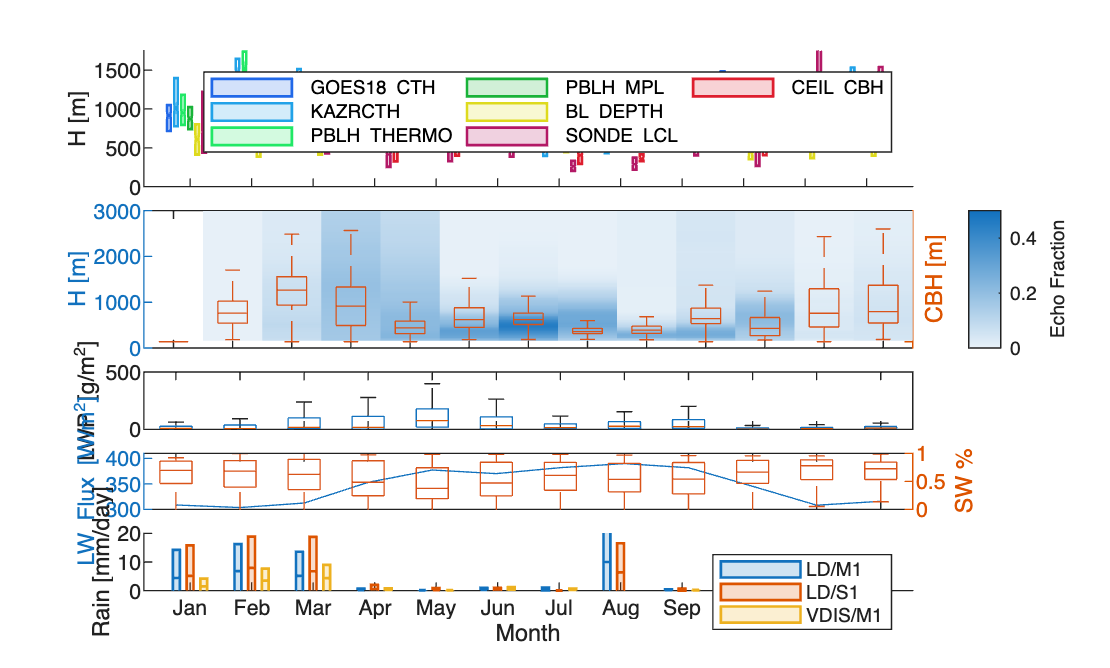

xticklabels([])
ylim([0 1])
ylabel('SW %')

yyaxis left
clear mean
yearlyLW  = mean([janLW febLW marLW aprLW mayLW junLW julLW augLW sepLW octLW novLW decLW],1);
plot(1:12, yearlyLW)
ylim([300 410])
xticklabels([])
ylabel('LW Flux [W/m^2]')

nexttile(echoyearly,7,[1 1])
stdRainfall = readtable("STD-Russel EPCAPE Rainfall.xlsx");
std2 = stdRainfall.data;
meanRainfall = readtable("MEAN-EPCAPE Russel Rainfall.xlsx");
mean2 = meanRainfall.Var2;
index2 = meanRainfall.Var3;
time = month(datetime(meanRainfall.Var1,"Format","uuuu/MM"));



q1 = mean2-std2;
q3 = mean2+std2;
min = mean2 - 2.*std2;
max = mean2+ 2.*std2;
bigdata = [min q1 mean2 mean2 q3 max];

datagraph = zeros(size(bigdata,1)*size(bigdata,2),1);
indexgraph = strings(size(bigdata,1)*size(bigdata,2),1);
monthgraph = zeros(size(bigdata,1)*size(bigdata,2),1);
for i = 1:6:(size(bigdata,1)*size(bigdata,2))
    datagraph(i:i+5) = bigdata((i+5)/6,:)';
    indexgraph(i:i+5) = index2((i+5)/6);
    monthgraph(i:i+5) = time((i+5)/6);
end

monthgraph = categorical(string(monthgraph),monthOrder);
boxchart(monthgraph,datagraph,'GroupByColor',indexgraph,'MarkerStyle','none','WhiskerLineStyle','none')
legend("LD/M1","LD/S1","VDIS/M1")
ylabel('Rain [mm/day]')
ylim([0 20])
xlabel('Month')
xticklabels(["Jan" "Feb" "Mar" "Apr" "May" "Jun" "Jul" "Aug" "Sep" "Oct" "Nov" "Dec"])

clear mean

std2

std2 =    10.1071
    8.4095
    0.5561
    0.1355
    0.7124
    0.5226
   10.2255
    0.2448
    0.9635
    1.5166
    4.1038
    9.7735
    8.6507
    4.2784
    4.6277


mean2

mean2 =     5.0385
    5.1621
    0.2095
    0.0812
    0.2879
    0.5898
    9.9985
    0.2039
    0.8174
    0.8531
    3.8120
    4.4319
    8.6403
    2.6676
    4.3580


index2 

index2 = 39×1 cell array
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-LD/M1'  }
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-VDIS/M1'}
    {'MEAN-LD/S1'  }
    {'MEAN-LD/S1'  }
    {'MEAN-LD/S1'  }
    {'MEAN-LD/S1'  }


time

time =      2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
     1
     2
     2
     3
